clear;
global SAVE_EXT;
global SAVE_DIR;
SAVE_EXT = "png";% figure saving conf (png, eps, etc...)
SAVE_DIR = "lab1/tex/images/";
mkdir(SAVE_DIR)

Task 1

T = 0.2;
K_CO = 5.7;

function task_1(exp_name)
    global SAVE_EXT;
    global SAVE_DIR;
    sim_res = sim("lab1/task1.slx", 4);
    clf;
    title("System state")
    hold on
    plot(sim_res.x.time, sim_res.x.data(:,1), 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-')
    grid on
    hold off
    exportgraphics(gcf, SAVE_DIR + exp_name + "_state." + SAVE_EXT)
    
end

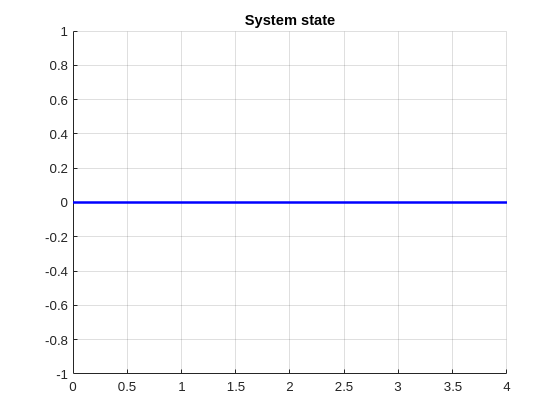

K_FB = 0.0;
task_1("task1_b__neutral")

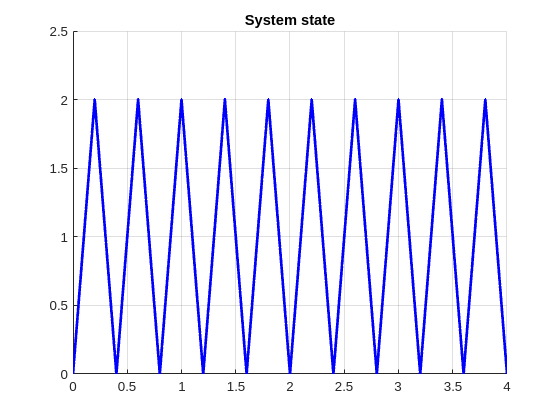

K_FB = 100/57;
task_1("task1_b__oscill")

K_FB = 2 / (T * K_CO);
task_1("task1_d__max")

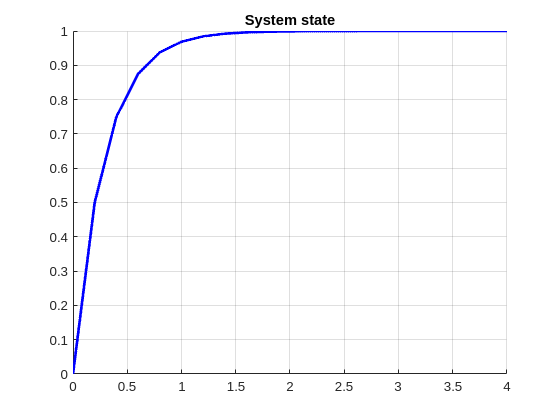

K_FB = 1 / (T * K_CO)* 0.5;
task_1("task1_d__no")

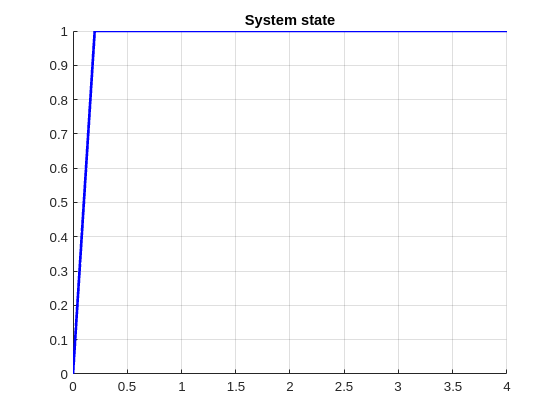

K_FB = 1 / (T * K_CO);
task_1("task1_e__optim")